# LINEAR SYSTEMS: Superposition and convolution

An introduction to the basic ideas of linear  systems theory, focusing on the tools of shift-invariant linear systems. We introduce the ideas of superposition,  shift-invariance,  and impulse response functions. These ideas are fundametal to many methods and analyses used in functional neuroimaging and throughout  engineering and science.

- Class:     Psych 204B

- Tutorial:  Linear Systems

- Author:    Wandell

- Date:       3.31.04

- Duration:   30 minutes

- Copyright:  Stanford University, Brian Wandell

This tutorial has a lot of reading at the front.

- Checked: 10/13/09 JW

- Checked: 10/13/10 BW

## What is a system?

Linear systems theory is a method of characterizing certain types of common systems.  A system is something that has an input and an output, and thus we can think of it as a function 


$$Out = L(In)$$


For example, the system might be a lens that  takes an image as an input and produces another image as an output. Or,  this system may be a biological system that takes metabolic activity in the brain as input and delivers the the BOLD response as output.

Characterizing the  input-output properties of a system by exhaustive measurements is usually impossible. When a system qualifies as a **linear system**, it is possible to use the responses to a small set  of inputs to predict the response to any  input. This makes it possible to characterize the system completely.

## The principle of superposition

Not all systems can be described using linear systems theory. To use linear methods to describe a system, it must satisfy the basic principle of superposition. In words the principle is this: 

If the response to input A is Ra, and the response to input B is Rb, then the response to the sum of A and B (A+B) is the sum of the  responses: Ra + Rb. In equation form this is


$$\begin{array}{l}
\textrm{If}\;\;\;\;\;\;L\left(a\right)=R_a \\
\textrm{and}\;\;L\left(b\right)=R_b ,\\
\textrm{then}\;L\left(a+b\right)=R_a +R_b 
\end{array}$$


### Homogeneity

There is one simple consequence of superposition that is often taken as  a special case and named the principle of homogeneity.  Suppose that the inputs are equal, namely, a = b.  It is easy to see that 


$$L\left(a+b\right)=L\left(2a\right)={2R}_a$$


In general, if s is any scalar, a linear system will satisfy the rule:


$$L\left(\textrm{sa}\right)={\textrm{sR}}_a$$


### Why it matters

An enormous number of simple systems satisfy superposition over a meaningful range of inputs.  Linear systems theory is a basic tool used throughout engineering, physics, and statistical modeling.   

In this tutorial, we will build up some of the tools of linear systems theory.  These include the use of matrices to describe a linear system, the very important special case of a shift-invariant linear system, and the associated ideas of the impulse response function

All of these ideas are used in functional neuroimaging.  In fact, nearly every field that uses linear systems theory develops its own terminology (jargon) to describe the general ideas of linear systems theory in the  specific context of that field.

## The hemodynamic response function (HRF) 

All time varying stimuli can be thought of as a series of impulses at different levels. We can approximate any complex stimulus as if it were simply the sum of a number of shifted and scaled impulses.  In neuroimaging, the hemodynamic response function (HRF) is the impulse response function. 

A shift-invariant linear system is a special case when the system responds in the same way to a given impulse, no matter when the impulse occurs in time.  That is, it doesn't matter what happened just before the impulse or what happens just after the impulse.  The response to the impulse will be the same.

The significance of the principle of superposition is this: If we know the impulse response function, we can predict the response to any stimulus (combinations of impulses).  We compute the response to each impulse and then add up all the results.

A remarkable feature of a shift-invariant linear (SIL) system is this: **To characterize shift-invariants linear (SIL) systems, we only need to measure the way the system responds to an impulse of a particular intensity. **That is enough to let us predict how the system will respond to all other stimuli.

The analysis of BOLD using linear systems presupposes that the responses are shift-invariant linear systems.  

### Testiing additivity

In neuroimaging, the principles of  superposition and shift invariance are essential to the ideas used in rapid event-related designs: The underlying assumption is that if you have two neural (or cognitive) events A and B occurring one after the other, then the BOLD response of A and the BOLD response of B  will be identical (but B will be shifted in time with respect to A) and thus total BOLD signal after these two events is a sum of two independent responses shifted in time:

  BOLD (A+B) = BOLD(A) + BOLD(B)

Next, we do some simple calculations with a model of the relationship between the stimulus and BOLD response.

set(0, 'DefaultLineLineWidth', 2);

## Read and plot aHemodynamic response function (HRF)

This is the default HRF from the famous SPM (Statistical Parameter Mapping) package.

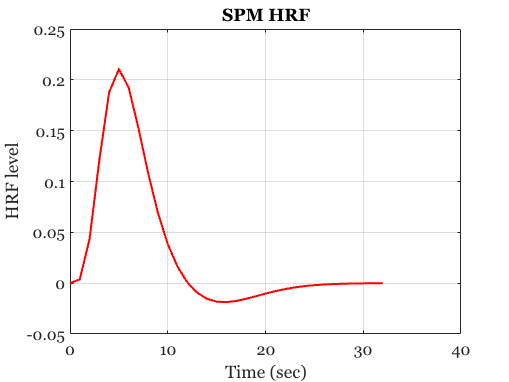

TR = 1;         % TR of 1 sec
[hrf,p]  = spm_hrf(TR);
hrfTimes = 0:p(7);   %Individual time samples of the HRF

figure;
plot(hrfTimes,hrf)
xlabel('Time (sec)'); ylabel('HRF level');
grid on; title('SPM HRF')

The default SPM HRF has an undershoot (negative region) towards the end.  The sum of the all the term of the HRF is 1, which is important.  

sum(hrf)

ans = 1.0000

This means that the HRF will preserve the mean value of the input signal.

## Simple forward calculation

Let's create an stimulus that is an impulse.  

% Let's imagine that each step is 0.1 sec (100 ms).
% The
tSteps = p(7)*10;
stimTimes = (1:tSteps)*0.1;

hrf = interp1(hrfTimes,hrf,stimTimes);

% We create one stimulus with an impulse event at time 1 sec
time1 = find(stimTimes == 1);
stim1        = zeros(1,tSteps);
stim1(time1) = 1;

% A second stimulus with an event at time 2 sec
time2 = find(stimTimes == 2);
stim2 = zeros(1,tSteps);
stim2(time2) = 1;

## Plot the stimulus and output of a linear system with the SPM HRF

We plot the two stimuli and then compute the expected BOLD response by using **convolution** of the stimulus with the HRF. Convolution is a mathematical operation that implements the superposition principle for a shift-invariant linear system. Each moment of the stimulus is an input, and the scaled and shifted HRF is added to the output. It is often written as an integral


$$O(t) = \int H(u)S(t-u) du$$


and sometimes using this notation


$$O = H*S$$


Throughout we use the circular convolution.  Ask me about that in class.

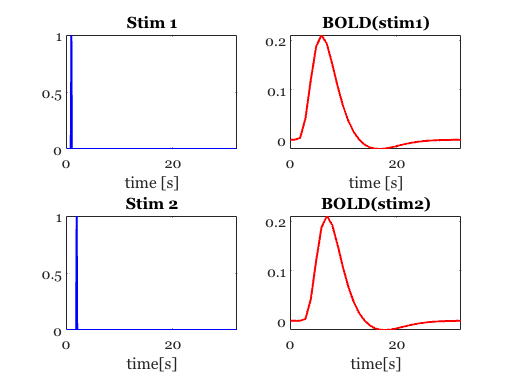

figure;
subplot(2,2,1); plot(stimTimes,stim1,'b-');
title('Stim 1')
xlabel ('time [s]')

% Compute the impact of the HRF
bold1 = cconv(stim1,hrf,tSteps);
subplot(2,2,2); plot(stimTimes,bold1,'r-')
title('BOLD(stim1)')
xlabel ('time [s]')

% Second stimulus and output
subplot(2,2,3);  plot(stimTimes,stim2,'b-');
title('Stim 2')
xlabel('time[s]')

bold2 = cconv(stim2,hrf,tSteps);
subplot(2,2,4); plot(stimTimes,bold2,'r-');
title('BOLD(stim2)');
xlabel('time[s]')

## Event-related design

Suppose a subject sees stimulus 1 and then and then later stimulus 2. According to the principle of superposition the output should be the sum of the individual events. Thus, we can compute the output by convolution of the sum of the two stimuli.  

% Here is the sum
stim3 = stim1 + stim2;

figure
subplot(3,1,1); plot(stimTimes,stim3,'bo-'); hold;

Current plot held


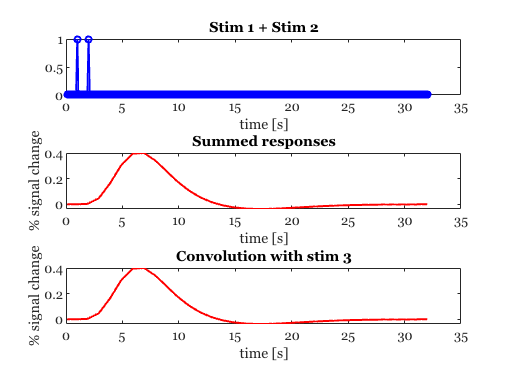

title('Stim 1 + Stim 2')
xlabel ('time [s]')

% Calculating the output using the superposition principle
BOLD3 = bold1(1:tSteps) + bold2(1:tSteps);

subplot(3,1,2); plot(stimTimes,BOLD3);
xlabel ('time [s]'); ylabel('% signal change')
title('Summed responses')

% This is the predicted response by convolution
bold3 = cconv(stim3,hrf,tSteps);
subplot(3,1,3);
plot(stimTimes,bold3)
xlabel ('time [s]')
ylabel('% signal change')
title('Convolution with stim 3')

## Working towards the block design

We start with blocks of two brief events that are separated in time. We then examine how the number of events and the spacing between events affects the predicted bold signal.

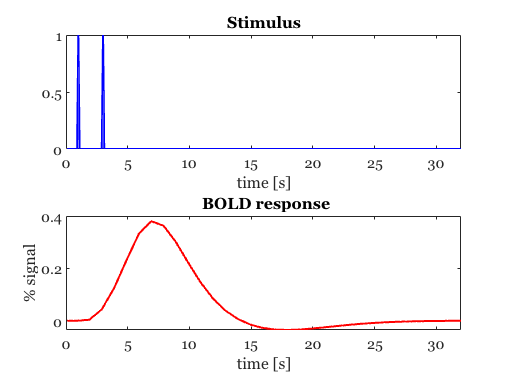

% 1st evetSteps at time 1
time1 = (stimTimes == 1);
stim1=zeros(1,tSteps);  stim1(time1)=1;

% 1st evetSteps at time2
time2 = (stimTimes == 3);
stim2 = zeros(1,tSteps);  stim2(time2) =1 ;

stim4 = stim1 + stim2;

% stimulus
figure;
subplot(2,1,1);
plot(stimTimes, stim4,'b-');
title('Stimulus'); xlabel ('time [s]')

% BOLD
bold1 = cconv(stim4,hrf,tSteps);
subplot(2,1,2);
plot(stimTimes,bold1);
ylabel('% signal'); xlabel ('time [s]')
title(' BOLD response')

## Two events close in time

Next, we move the two events closer in time

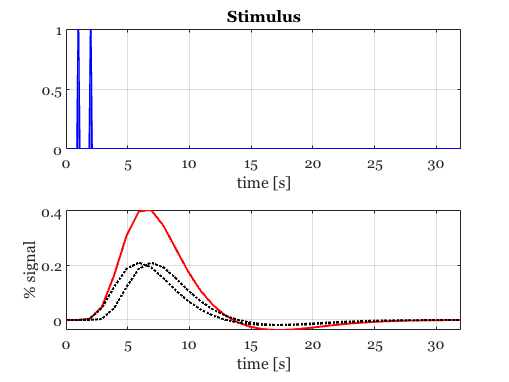

% Move the 2nd event at 2 sec.
time2 = (stimTimes == 2);
stim2 = zeros(1,tSteps); stim2(time2) = 1 ;

stim5 = stim1 + stim2;

figure;
subplot(2,1,1);
plot(stimTimes, stim5,'b-'); grid on;
xlabel ('time [s]'); title('Stimulus');

bold1 = cconv(stim5,hrf,tSteps);
subplot(2,1,2);
plot(stimTimes,bold1); grid on;
xlabel ('time [s]'); ylabel('% signal');

% Add the underlying responses
hold on;
bold1 = cconv(stim1,hrf,tSteps); plot(stimTimes,bold1,'k:');
bold2 = cconv(stim2,hrf,tSteps); plot(stimTimes,bold2,'k:');

## Three events 

All close in time

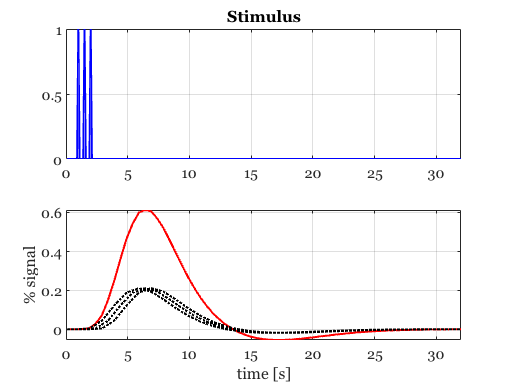

% 3rd event at 1.5 sec
time3 = (stimTimes == 1.5);
stim3 = zeros(1,tSteps);
stim3(time3) = 1;
stim6 = stim1 + stim2 + stim3;

figure;
subplot(2,1,1);
plot(stimTimes, stim6,'b-'); grid on;
title('Stimulus');

bold1 = cconv(stim6,hrf,tSteps);
subplot(2,1,2);
plot(stimTimes,bold1);grid on;
ylabel('% signal'); xlabel ('time [s]')

% The underlying responses
hold on;
bold1 = cconv(stim1,hrf,tSteps); plot(stimTimes,bold1,'k:');
bold2 = cconv(stim2,hrf,tSteps); plot(stimTimes,bold2,'k:');
bold3 = cconv(stim3,hrf,tSteps); plot(stimTimes,bold3,'k:');

## A block

Now we calculate for a stimulus that is on continuously for 2 seconds (time 1 sec to time 3 sec)

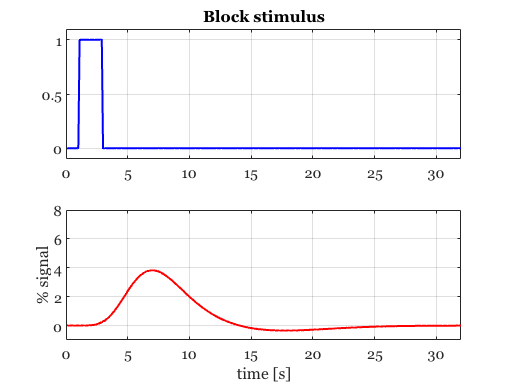

time7 = (stimTimes > 1 & stimTimes < 3);
stim7 = zeros(1,tSteps);
stim7(time7) = 1;

figure;
subplot(2,1,1);
plot(stimTimes, stim7,'b-'); grid on;
title('Block stimulus'); set(gca,'ylim',[-0.1 1.1]);

bold1 = cconv(stim7,hrf,tSteps);
subplot(2,1,2);
plot(stimTimes,bold1);grid on;
ylabel('% signal'); xlabel ('time [s]'); set(gca,'ylim',[-1 8]);

Compare the y-axis on this BOLD response with the y-axis on the previous graphs.  Keeping the stimulus on longer increases the level.  Let's check that by setting the stimulus 

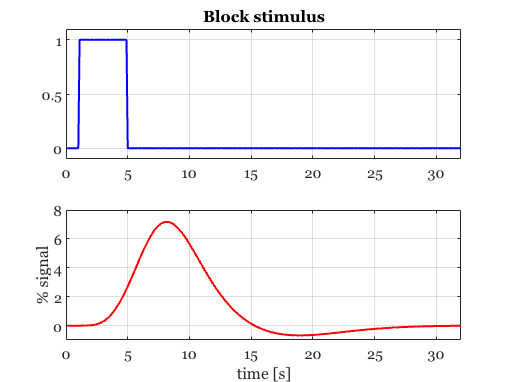

time7 = (stimTimes > 1 & stimTimes < 5);
stim7 = zeros(1,tSteps);
stim7(time7) = 1;

figure;
subplot(2,1,1);
plot(stimTimes, stim7,'b-'); grid on;
title('Block stimulus'); set(gca,'ylim',[-0.1 1.1]);

bold1 = cconv(stim7,hrf,tSteps);
subplot(2,1,2);
plot(stimTimes,bold1);grid on;
ylabel('% signal'); xlabel ('time [s]'); set(gca,'ylim',[-1 8]);

## Different input levels

We are calculating the BOLD response as a series of impulse responses from the stimulus.  At each moment in time that the stimulus is on, we add in the impulse response.  For all of the examples, we treated the stimulus input value as 1.  

Suppose that we have two stimuli, and the two stimuli are not equally effective.  Perhaps the second stimulus is only half as effective as the first one.  How would we represent that, and what would the predicted response be?

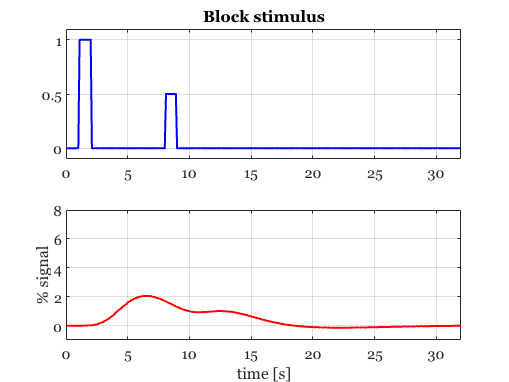

% This is the first stimulus with effectiveness 1
time1 = (stimTimes > 1 & stimTimes <= 2);
stim1 = zeros(1,tSteps);
stim1(time1) = 1;

% The second stimulus is delayed and has half the effectiveness
time2 = stimTimes > 8 & stimTimes < 9;
stim2 = zeros(1,tSteps);
stim2(time2) = 0.5;

% The sum of the stimuli
figure;
subplot(2,1,1)
plot(stimTimes,stim1 + stim2,'b-');
grid on;
title('Block stimulus'); set(gca,'ylim',[-0.1 1.1]);

% The BOLD responses
subplot(2,1,2)
bold1 = cconv(stim1 + stim2,hrf,tSteps);
subplot(2,1,2);
plot(stimTimes,bold1);grid on;
ylabel('% signal'); xlabel ('time [s]'); set(gca,'ylim',[-1 8]);

## Convolution interpreted from the output side

We have been calculating how the stimulus at a moment in time contributes to output values at different times.   Now, let's consider the system from the perspective of the output. At each moment in time, which of the input signals contributed to the output?

To visualize this, let's plot the contributing impulse responses.

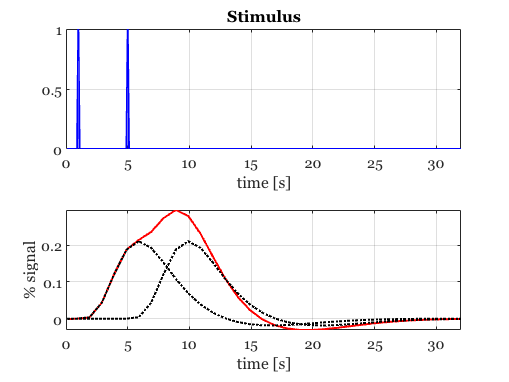

% First event at 1 sec
time1 = (stimTimes == 1);
stim1 = zeros(1,tSteps);
stim1(time1) = 1;

% Second event at 5 sec
time2 = (stimTimes == 5);
stim2 = zeros(1,tSteps);
stim2(time2) = 1 ;

figure;
subplot(2,1,1);
plot(stimTimes, stim1 + stim2,'b-'); grid on;
xlabel ('time [s]'); title('Stimulus');

subplot(2,1,2);
bold1 = cconv(stim1 + stim2,hrf,tSteps);
plot(stimTimes,bold1); grid on;
xlabel ('time [s]'); ylabel('% signal');

% Show the individual contributions
hold on;
bold1 = cconv(stim1,hrf,tSteps); plot(stimTimes,bold1,'k:');
bold2 = cconv(stim2,hrf,tSteps); plot(stimTimes,bold2,'k:');

The output at 5 sec is due entirely to the stimulus at 1 sec.  The output at 8 sec, however, is caused by a combination of the signal at 1 sec and 5 sec.  And the output at 15 sec has a positive contribution from the stimulus at 5 sec and a negative contribution from the stimulus at 1 sec.  

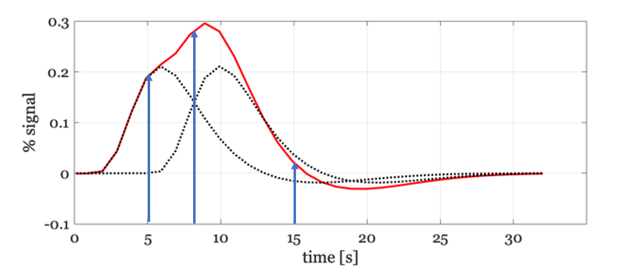

## Multiple events

Now suppose we have an event every second for the first five seconds.  Let's draw the picture

stim = zeros(1,tSteps);
for ii=1:5
    thisTime = find(stimTimes == ii);
    stim(thisTime) = 1;
end
figure;
subplot(3,1,1);
plot(stimTimes, stim,'b-'); grid on;
xlabel ('time [s]'); title('Stimulus');


Now add in the individual stimuli.  The dotted curves add up to the red curve.

subplot(3,1,2);
bold = cconv(stim,hrf,tSteps); plot(stimTimes,bold,'r-');
hold on;
for ii=1:5
    stim = zeros(1,tSteps);
    thisTime = find(stimTimes == ii);
    stim(thisTime) = 1;
    bold = cconv(stim,hrf,tSteps); plot(stimTimes,bold,'k:');
end
% Zoom in on the time axis
grid on; xlabel('Time (s)')


Let's  zooms in on the contributing responses.  At each moment in time we are adding in some one of the terms from the HRF, but shifted in time.

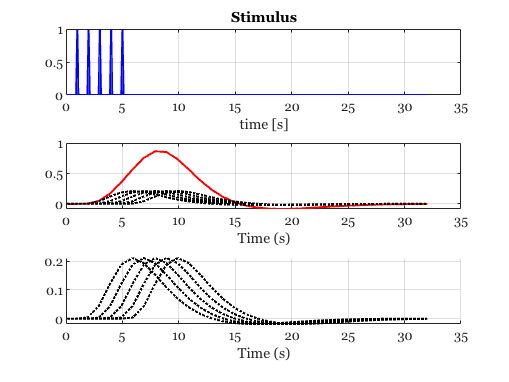

subplot(3,1,3)
hold on;
for ii=1:5
    stim = zeros(1,tSteps);
    thisTime = find(stimTimes == ii);
    stim(thisTime) = 1;
    bold = cconv(stim,hrf,tSteps); plot(stimTimes,bold,'k:');
end
grid on; xlabel('Time (s)')

Finally, let's suppose the stimuli aren't all the same.  Some are bigger and some are smaller.

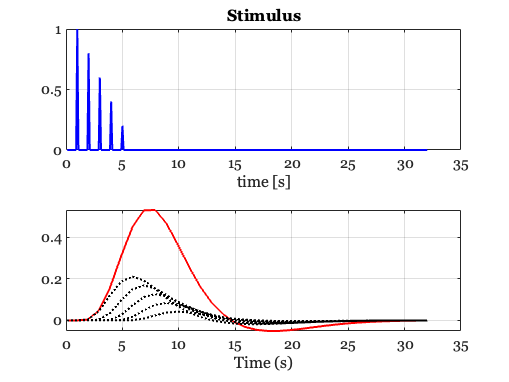

effect = (5:-1:1)/5;   % The 5 stimuli
stim = zeros(1,tSteps);
for ii=1:5
    thisTime = find(stimTimes == ii);
    stim(thisTime) = effect(ii);
end

figure;
subplot(2,1,1);
plot(stimTimes, stim,'b-'); grid on;
xlabel ('time [s]'); title('Stimulus');

subplot(2,1,2);
bold = cconv(stim,hrf,tSteps); plot(stimTimes,bold,'r-');
hold on;
for ii=1:5
    stim = zeros(1,tSteps);
    thisTime = find(stimTimes == ii);
    stim(thisTime) = effect(ii);
    bold = cconv(stim,hrf,tSteps); plot(stimTimes,bold,'k:');
end
% Zoom in on the time axis
grid on; xlabel('Time (s)')

If we think of the stimulus as a continuous function then we would have multiple contributions, That idea is expressed in the convolution formula:


$$O(t) = \int H(u)S(t-u) du$$


The output at each moment in time is a weighted sum of a shifted copy of the stimulus.  The weights are the impulse response $H(u)$ and this is the stimulus, constantly shifting in time, $S(t-u)$.

## The importance of harmonics

Harmonics (sinusoids and cosinusoids) play a very important role in shift-invariant linear systems.  The reason is simple:  If you put a harmonic at some frequency into the system, the response will be a harmonic at the same frequency.  The response may have a different amplitude, or be shifted in phase, but it will still be a harmonic at the input frequency.

Here is a calulcation using a sinusoidal input stimulus. 

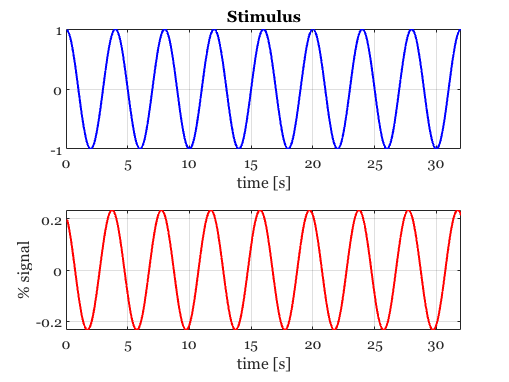

freq = 1/4;  % Choose freq = 1/N where N = 2^integer
stim = cos(2*pi*freq*stimTimes);

figure;
subplot(2,1,1);
plot(stimTimes, stim,'b-'); grid on;
xlabel ('time [s]'); title('Stimulus');

subplot(2,1,2);
bold1 = cconv(hrf,stim,tSteps);
plot(stimTimes,bold1); grid on;
xlabel ('time [s]'); ylabel('% signal');

Notice that if we put a harmonic in, we measure a harmonic as the result.  The amplitude and phase of the harmonic will depend on the HRF.  (We have to be careful about choosing the frequency, there can be sampling artifacts).  

## Thought Questions

### QUESTION 1

Researchers presented a subject with an image of a face and measured the hemodynamic response to this image. Then they showed the same stimulus again and found that the response peaked at the same time, but the amplitude of response was half the amplitude of the first presentation. Is the response for the second presentation expected from a linear system? Explain. 

### QUESTION 2

Researchers presented stimuli in 2 blocks. In the first block they presented flashing checkboards at a rate of 1Hz for 10 seconds. In the second block they presented flashing checkerboards at a rate of 1hz for 20 seconds. How will the amplitude and/or duration of the block-response change between conditions? Explain.

### QUESTION 3

Researchers presented stimuli in 2 conditions. In the first condition they presented a tone for 1 second, waited for 8 seconds, and presented a second tone for 1 second. In the second condition, they presented a tone for 1 second, waited 1 second, and presented a second tone for 1 second. How will the response differ in amplitude and/or duration between the two conditions? A plot/graph will be useful in explaining the answer.